# Convert ASCII Data Files Into Binary Data Files

## Read the ASCII Data File Into MATLAB

Specify the input file name.

input_file_ascii = '/home/vadim/Work/Sandbox/Ajay_PCAP/processed_data.txt';
input_file_binary = '/home/vadim/Work/Sandbox/Ajay_PCAP/processed_data';

Read all the values in the ASCII file into a MATLAB variable. The code assumes the ASCII data is a single column of values.

fileID = fopen(input_file_ascii,'r');
formatSpec = '%i\n';
A_raw = fscanf(fileID,formatSpec);
fclose(fileID);

Determine the size of the MATLAB variable holding the ASCII values.

[num_values, n] = size(A_raw);

Create a fixed point math object and specify its overflow property to be wrap.

F = fimath('OverflowAction', 'Wrap');

Assign the fixed point math object to a new variable and then assign to that variable ASCII values read in earlier. This is done b/c of MATLAB's apparently idiotic "feature" where making the assignment and then changing the property will not change the data with it, so the assignment has to be done to an object that's already configured with the fixed-point properties desired.

% Create an empty fixed-point object.
A_pre = sfi((1:num_values), 16, 0);
% Assign the desired fixed-point properties to the object, and create a new variable out of that.
A = setfimath(A_pre, F);
% Assign the desired variable values to an object already pre-configured with the desired fixed-point properties.
A(1:end) = A_raw(1:end);

## Write the Data into a Binary File

Write the data contained in the MATLAB variable A into a binary file. The data is written as signed 16 bit integers.

fileID = fopen(input_file_binary,'w');
fwrite(fileID,A.data,'int16');
fclose(fileID);

## Read the Binary File into a MATLAB Variable

The following code relies on MATLAB filling the array column-by-column. The first row of the array will contain all of the real (I) values and the second row will contain all of the imaginary (Q) values.

fid = fopen(input_file_binary, 'r');
%fseek(fid,4*1e6,'bof');                      % skip first 1e6 samples, 4e6 bytes
x_raw = fread(fid,[2,num_values],'int16');   % for system generator use this

## Plot the Data

Create variables for the real (I) values and the imaginary (Q) values.

%I = x_raw(1,:)';
%Q = x_raw(2,:)';
A_val = A.value;
I = A.data(1:2:end)';
Q = A.data(2:2:end)';

Create a time index variable to use for plotting.

T = [1:length(I)]';
%T = T/30e6;

Plot the real and imaginary data as two lines on a single plot.

plot(T,I,T,Q);

Error using plot
Data must be a single matrix Y or a list of pairs X,Y.

xlabel('Sample Number');
ylabel('Sample Value');
legend('real','imaginary');

## Plot the Magnitude and Phase of the Data

Create a complex variable using the real and imaginary data

x = complex(I,Q);

Compute the magnitude.

xmag = abs(x);

Comput the phase.

xphase = angle(x);

Plot the magnitude and phase.

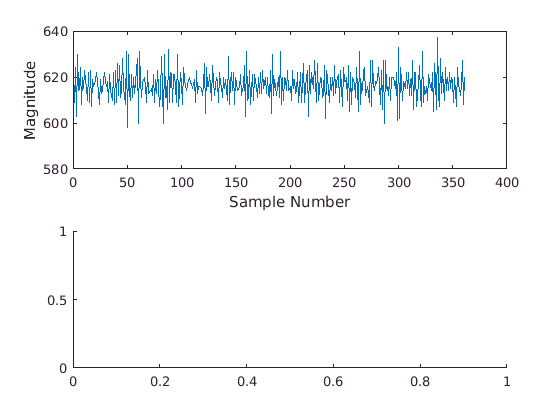

subplot(2,1,1);
plot(T,xmag);
xlabel('Sample Number');
ylabel('Magnitude');
subplot(2,1,2);

plot(T,unwrap(xphase));

Undefined function 'diff' for input arguments of type 'embedded.fi'.

Error in unwrap>LocalUnwrap (line 87)
dp = diff(p,1,1);                % Incremental phase variations

Error in unwrap (line 67)
   q(indf,j) = LocalUnwrap(p(indf,j),cutoff);

xlabel('Sample Number');
ylabel('Phase (radians)');

% Set up the time vector to be used for all input data.
time = 1:length(T);

% Set up the real data vector.
real_sig_in.time = time.';
real_sig_in.signals.values = I;

% Set up the imag data vector.
imag_sig_in.time = time.';
imag_sig_in.signals.values = Q;
